# **TRAYECTORIA III**

**Jesús Alejandro Gómez Bautista | A01736171**

Tomando como base nuestro código para la resolución de la actividad 1.4, realizé algunas modificaciones, principalmente centradas en las coordenadas y en el punto de partida de nuestro robot, para describir la misma trayectoria que se describe en la gráfica.

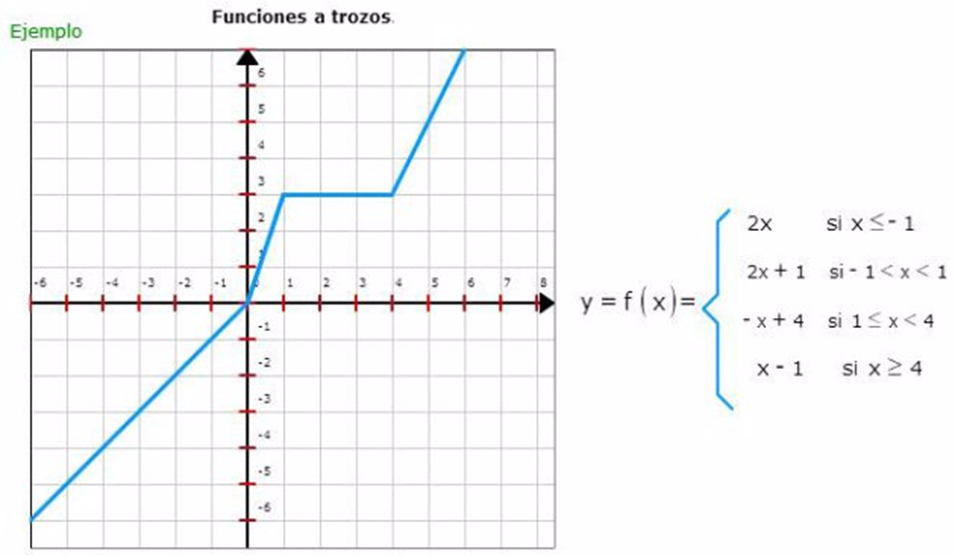

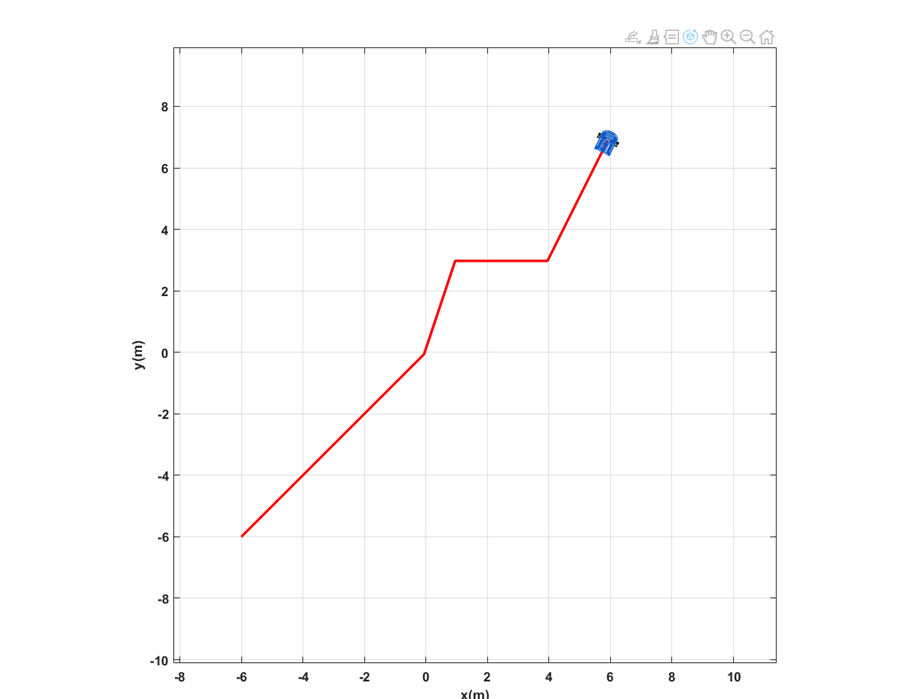

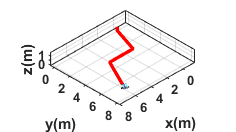

clear
close all
clc
load Uniciclo_6.mat

%%%%%%%%%%%%%%%%%%%%%%%%%%%% COORDENADAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
coordenadas = [-6,-6 ; 0,0 ; 1,3 ; 4,3 ; 6,7]; %Trazo de una trayectoria

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ts = 0.1;            % Tiempo de muestreo en segundos (s)
velocidad_lineal = 2; %Velocidad de 2m/S

r = zeros(1,size(coordenadas, 1)); 
radLocal = zeros(1,size(coordenadas, 1));
radGlobal = zeros(1,size(coordenadas, 1));
side_length_local = zeros(1,size(coordenadas, 1));
side_length_global = zeros(1,size(coordenadas, 1));

for j = 1:size(coordenadas, 1)-1 %Para cada coordenada - 1
    punto1 = coordenadas(j, :);
    punto2 = coordenadas(j+1, :);
    r(j) = sqrt((punto2(1)-punto1(1))^2 + (punto2(2)-punto1(2))^2);%Se calcula la distancia
    radLocal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1)); % Calcula el ángulo en radianes
    side_length_local(j) = round(r(j)/ts/velocidad_lineal) + 1; %Se calcula la longitud local
    if j==1
        radGlobal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1)); % Calcula el ángulo en radianes
        side_length_global(j) = side_length_local(j);
    else
        radGlobal(j) = atan2(punto2(2)-punto1(2), punto2(1)-punto1(1))-radLocal(j-1); % Calcula el ángulo en radianes
        side_length_global(j) = side_length_local(j)+side_length_global(j-1); 
    end
    
end


distancia_total = 0;
for j=1:size(coordenadas, 1)-1
    distancia_total = r(j) + distancia_total;
end

tiempo_recorrido = distancia_total/velocidad_lineal+((size(coordenadas, 1)-1)*ts); %Tiempo de recorrido

tf = tiempo_recorrido;             % Tiempo de simulacion en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = -6;    % Posicion inicial eje x
y1(1) = -6;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%


u = velocidad_lineal*ones(1, N); % Velocidad lineal de referencia (m/s)
w = zeros(1, N); % Velocidad angular de referencia (rad/s)

for i=1:N
    if i == 1
        w(i) = radGlobal(1)/ts;
        u(i) = 0;
    end
    if i == 1+side_length_global(1)
        w(i) = (radGlobal(2))/ts;
        u(i) = 0;

    end
    if i == 1+side_length_global(2)
        w(i) = radGlobal(3)/ts;
        u(i) = 0;
    end
    if i == 1+side_length_global(3)
        w(i) = radGlobal(4)/ts;
        u(i) = 0;
    end
    
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([135 35]); % Orientacion de la figura
axis([-20 20 -20 20 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    xlim([-1.49 8.07])
    ylim([-0.48 8.39])
    zlim([0.000 1.366])

    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

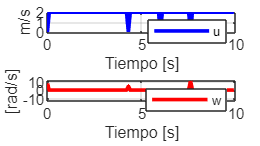


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');